# s_oeBloodFluorophoreTongueSrch 

The notes are in s_oeBloodFluorophoreLipSrch.mlx.

POSSIBLY DEPRECATED. NOT SURE.

From 500-600nm, there is an excellent fit with the {'collagen1','KeratinPalero','FADLin'} fluorophores.  The deviation is mainly with the 450nm excitation light.  We think there was some light leaking through.  Joyce actually knows.  When we do the fits from 520-600 nm, even the 450 nm excitation light nails the data perfectly.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;

## Create fluorophore matrix and read database 

We create the base fluorophore emissions matrix.  It does not include blood (fluorophoresB).  Below, we sweep through different potential levels of blood optical density, checking how well the modified fluorophore matrix predicts the data samples.  Notice that the effective optical density of blood can depend on the wavelength of the excitation light.  Some lights will penetrate into the skin (substrate) more deeply than others, thus creating a longer path through the blood.

We tried many fluorophore files from the literature. These are described in in **s_oeFluorophoreEmissions.mlx**.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

**Things we tried.**

- fluorophoreNames = {'collagen1','FAD_webfluor'}; -  Not enough dimensions. Fails to fit the data closely.

- fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'}; - Never chooses elastin

- fluorophoreNames = {'collagen1','FAD_webfluor','KeratinValdez'}; - Replaced NADH with Keratin.  Removed elastin. Too flat around 540, and a deep dive around 580.  General slope is OK.

- fluorophoreNames = {'collagen1','KeratinValdez','FADValdez'}; - Way off. Doesn't even get an OK fit of the blood.

- fluorophoreNames = {'CollagenWuQu','FADLin'}; - Way off, as above. Fails with blood

- fluorophoreNames = {'CollagenWuQu','FADValdez'}; - Way off as above.

- fluorophoreNames = {'CollagenWuQu','FAD_webfluor'}; - FIt is bad, but the blood is OK.

- fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'}; - Another blood miss.

- fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'}; - This collagen is goofy, and the fits are bad including the blood.

**Our winners so far**

- fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'}; - Best fit so far.  

- fluorophoreNames = {'collagen1','NADH_webfluor','FADLin'}; - Still good if we swap collagen1 for ColalgenWuQu.  That's a good thing.  

- fluorophoreNames = {'collagen1','KeratinPalero','FADLin'}; -  This keratin is close to NADH

We should also try deoxygenated blood at some point, by adding in a collagen-deoxy column.

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
odError = zeros(numel(odLevels),numel(subjects));  
ods = zeros(numel(subjects),1);    
rmse = zeros(size(subjects));

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 30.00
OD across subjects for 405/415nm 22.00
OD across subjects for 405/415nm 24.00
OD across subjects for 405/415nm 28.00


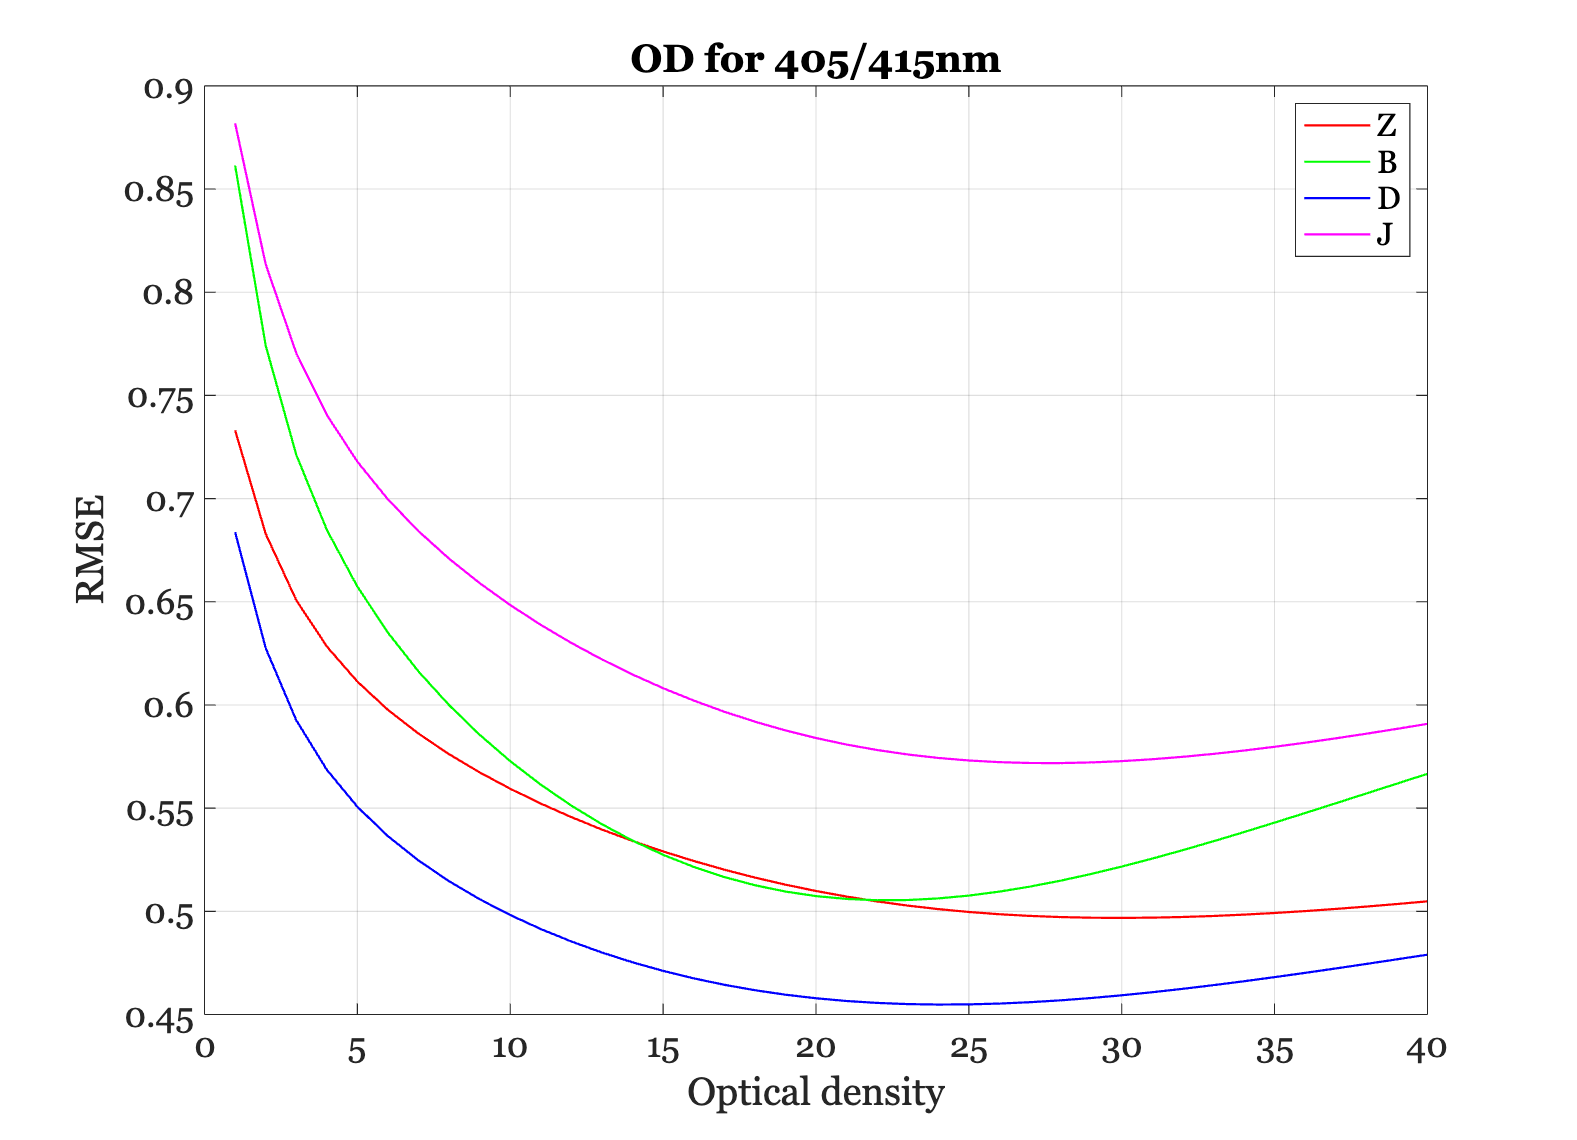


% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the proper optical density and plot

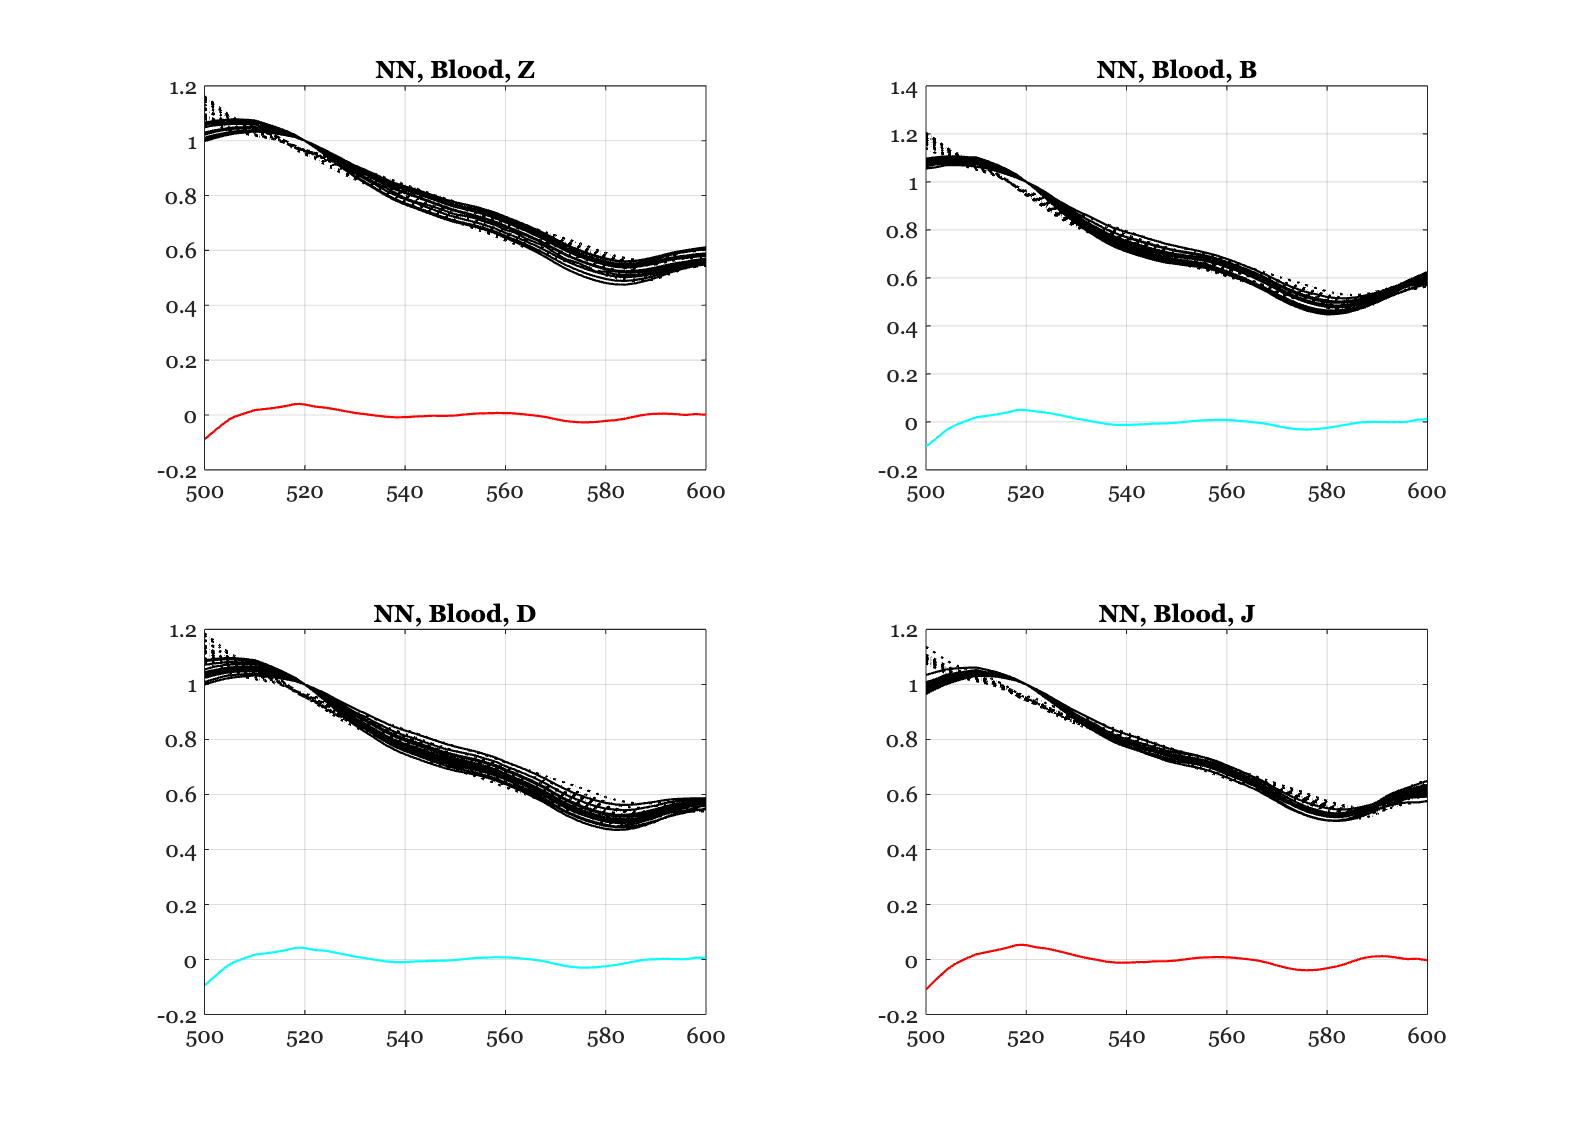

Subject Z
    6.6557    6.6695    6.0544    7.4483    6.9677    6.3479    6.5779    6.1857    6.2636    5.9164    7.2720    7.5274    5.0712    5.4648    5.3784
    2.8627    2.8053    2.7465    2.9091    2.4258    2.5575    2.4444    2.6666    2.5256    2.5529    2.4710    2.9078    2.7224    2.6943    2.6978
    0.3594    0.3756    0.3951    0.3402    0.4671    0.4339    0.4660    0.4071    0.4457    0.4380    0.4526    0.3329    0.4001    0.4035    0.4031

Subject B
    9.4108    6.7189    7.9019   11.2369    9.4900    9.8560    8.9851   10.7306    9.0269    9.6367    8.6838    8.3438    7.1278    8.2844
    2.6638    2.5736    2.5943    2.7036    2.7439    2.7931    2.8396    2.6968    2.7417    2.7792    2.8356    2.6927    2.6666    2.6394
    0.3451    0.3989    0.3797    0.3088    0.3187    0.3015    0.2997    0.3167    0.3237    0.3074    0.3037    0.3454    0.3682    0.3590

Subject D
    6.8352    7.2787    7.8492    5.7291    5.3566    5.8677    6.4013    5.4965    5.4519  

ieFigure;
tiledlayout(2,2);

deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 5;

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames]  = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end
    residual = tongueData - fluorophores*wgtsNN;
    rmse(ii) = norm(residual(:),2);

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:', ...
        wave,mean(residual,2));
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

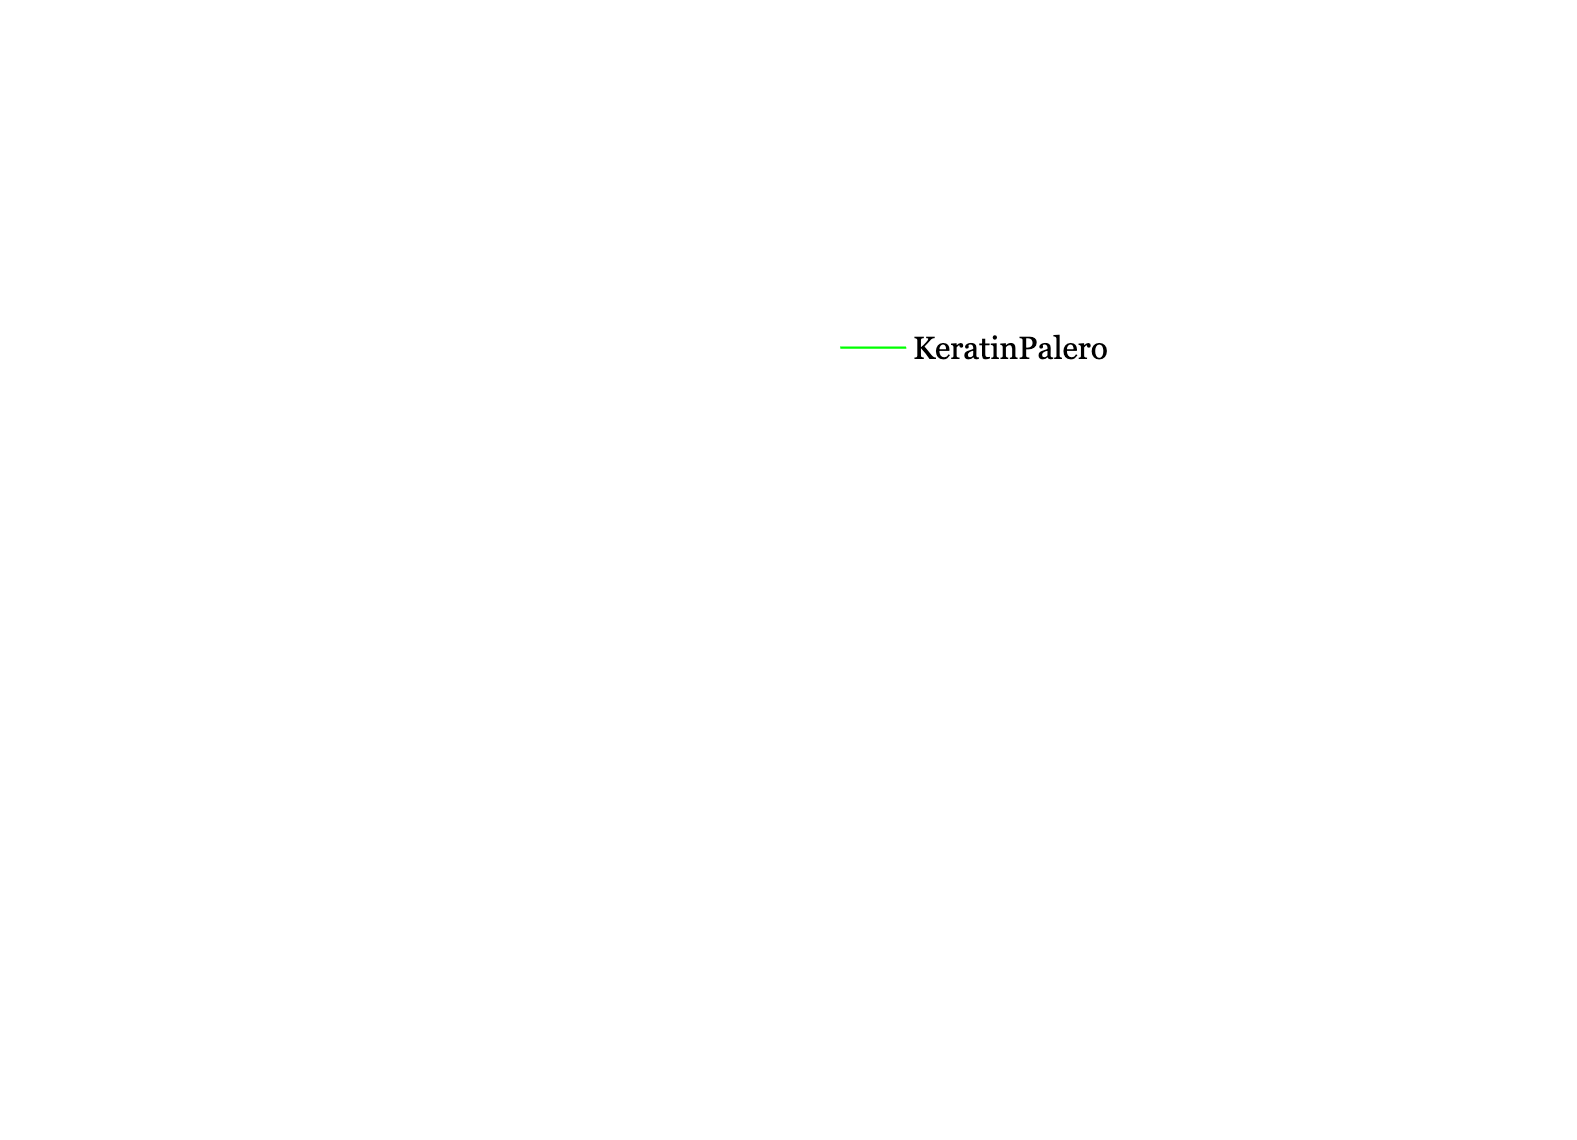


ieFigure; 
mx = max(fluorophores);
plot(wave,fluorophores*diag(1./mx));
title('Scaled fluorophores');
legend(fluorophoreNames);

legend(["collagen1-oxy", "KeratinPalero", "FADLin"], "Position", [0.4630 0.6080 0.3095, 0.1743])


disp(rmse); 

    0.8175    0.9667    0.8541    1.0891



## Create 450 nm blood optical density levels

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','tongue',...
        'e wave',450);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 40.00
OD across subjects for 405/415nm 31.00
OD across subjects for 405/415nm 28.00
OD across subjects for 405/415nm 39.00


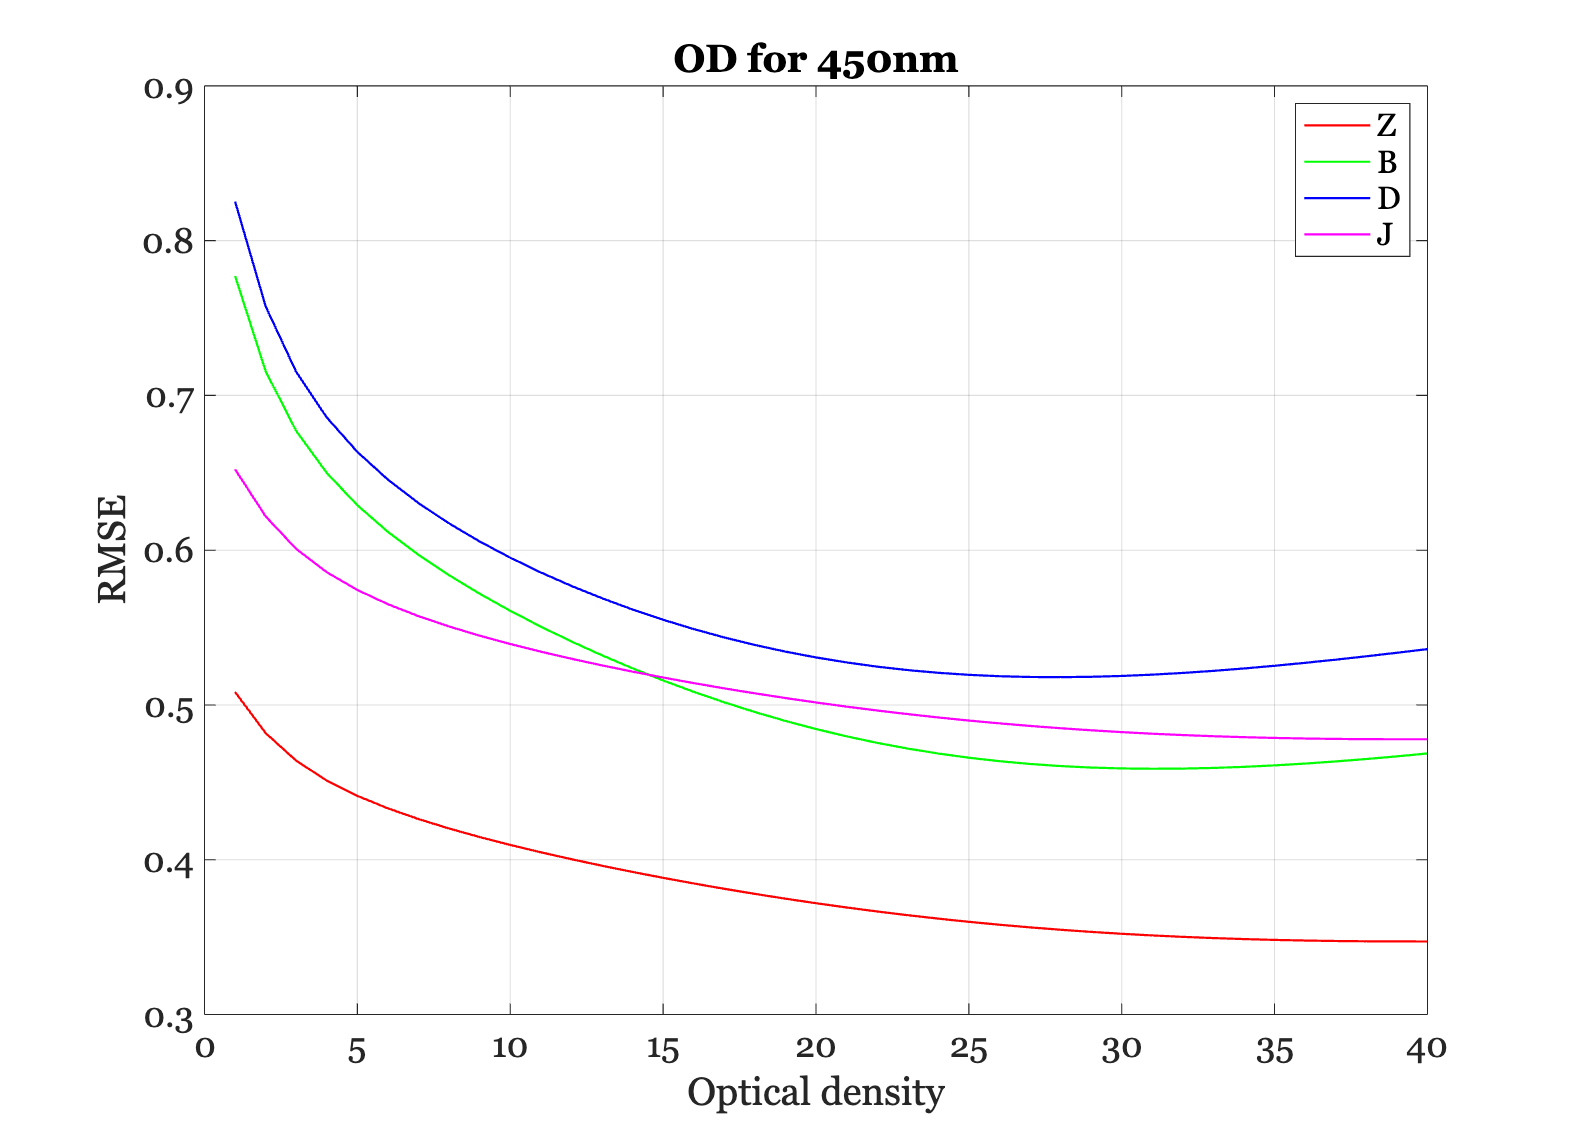



% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## 450 nm excitation light

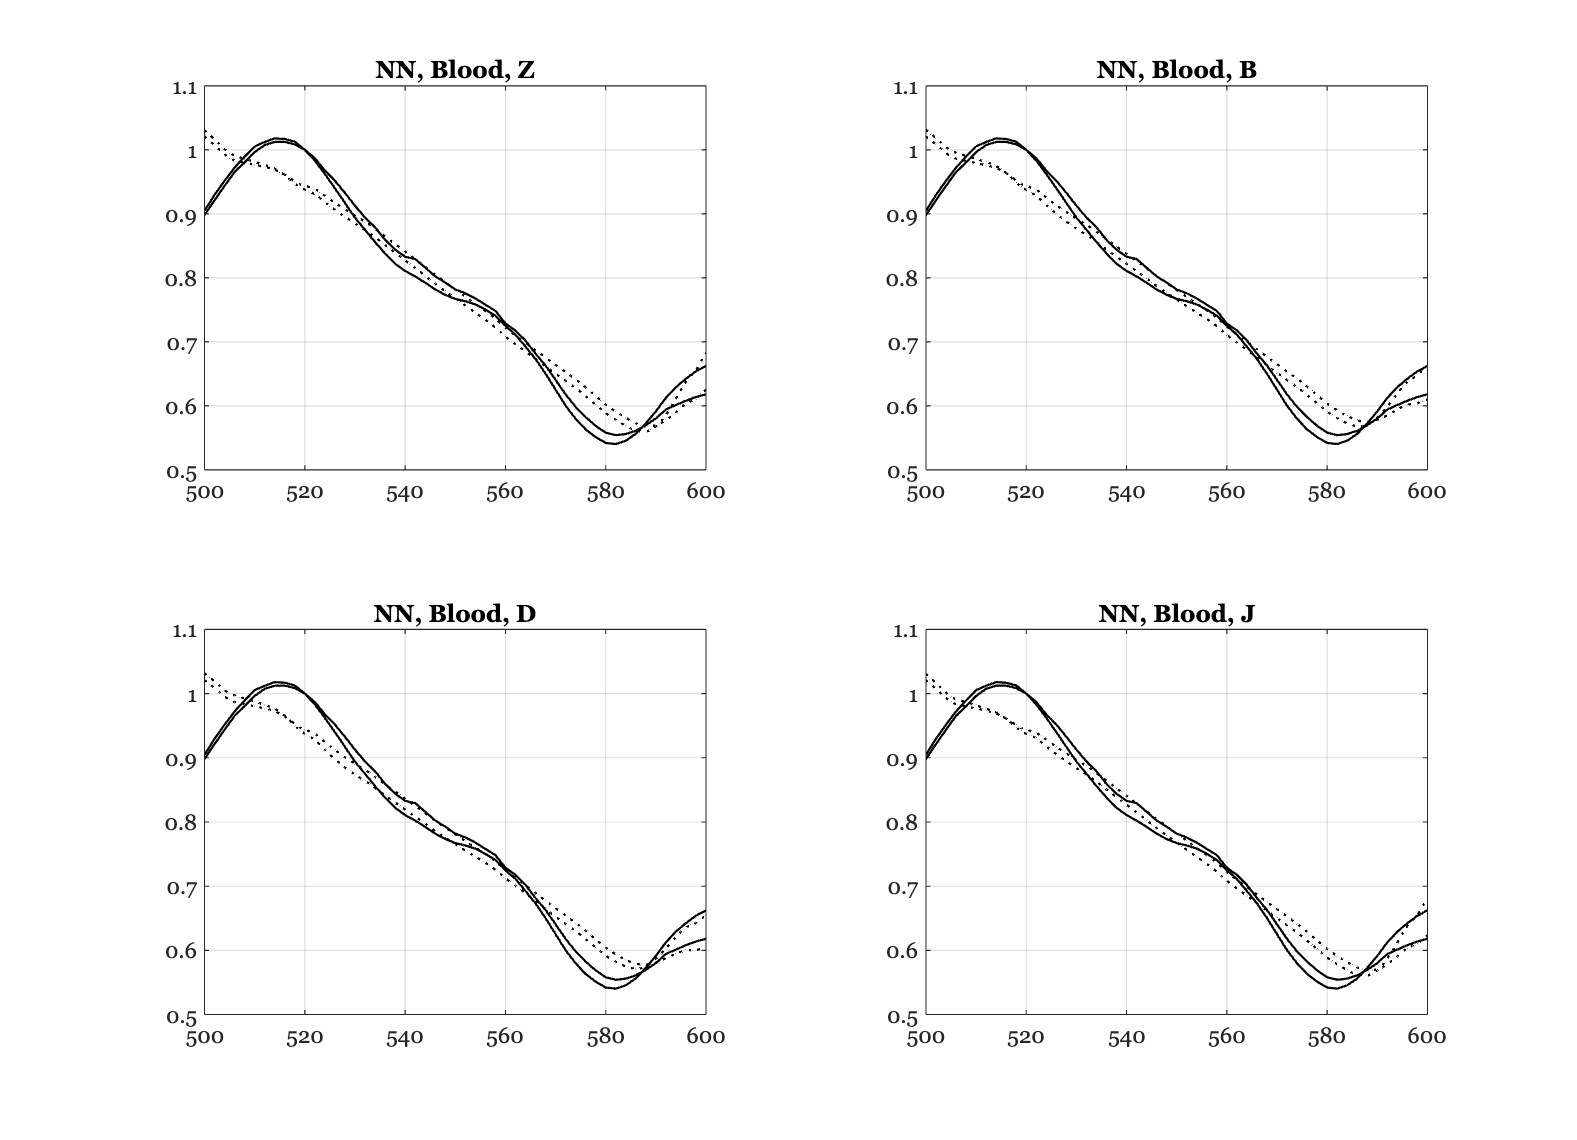

Subject Z
   12.5930    8.2680
    2.3008    2.2819
    0.4761    0.4928

Subject B
    9.8764    6.3539
    2.1820    2.2059
    0.4885    0.5010

Subject D
    8.9772    5.7268
    2.1286    2.1727
    0.4940    0.5044

Subject J
   12.2903    8.0539
    2.2905    2.2751
    0.4772    0.4935



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)
    wgtsNN = zeros(size(fluorophoresB,2),size(tongueData,2));

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end